## CA1: Snakes & Ladders (...& Data Science)

This first assignment is split into two parts. In the first part you will fill in the missing parts of code to create a working Snakes & Ladders game with a graphical user interface (GUI). In the second part you will do some data science based on the game.

**The rules of Snakes & Ladders are:**

- Two players participate

- Every player throws the die in their turn by pressing <Enter>

- You move as many steps on the board as the die number says

-  If you land on a ladder, you climb it

- If you land on a snake, you slide down it

- The first player to reach tile 100 WINS

All lines marked with a "**Q**" have accompanying lines "***Answer: *****TODO**". These are questions that need to be answered properly for a full score on this assignment.

## Part 1: Playable Snakes & Ladders

We have already implemented a skeleton of the game, so your job is to fill out the missing parts which are explained in the sections 1.1, 1.2, and 1.3.

**NB: **In this part of the assignment, you only need to consider the three functions "rollDice", "moveGamePiece", and "checkPosChange" located at the end of this file. You do not need to add or change anything in the sections "Preparing the Game" and "Game Loop". However, feel free to make additions and changes (obviously without changing the core functionality of the game) as long as they are documented.

**NB2: **After running the game, make sure you click in the command window since this is how Matlab takes keyboard input.

### 1.1: Roll the Dice (10%)

In this first task, finish the function called "rolldice" that should return a random integer between 1 and 6. The function does not need any input. 

Functions are defined at the end of Matlab files, so scroll down to the heading "Functions" and find the empty "rolldice" function.

**Q: **Give a short explanation of you approach to solving this task, and document any changes you made to the provided code.

***Answer: *****TODO**

### 1.2: Plot the Players (20%)

Next you should fix the plotting of the players. If you run the game now, you can see the two players being plotted in the top left corner, position (1,1). Fix the function "moveGamePiece" so that the player pieces are positioned inside the correct tile on the board. The function is at the bottom of this file, and the parts that you should implement are marked with TODOs with additional explanation.

**Q: **Give a short explanation of you approach to solving this task, and document any changes you made to the provided code.

***Answer: *****TODO**

### 1.3: Add Sliding and Climbing (10%)

As you may have noticed when testing the game, the snakes and ladders seem to have no effect on the players. It is now your task to add this functionality to the game. The function you should complete in this task is called "checkPosChange" and can be found at the bottom of this file.

**Q: **Give a short explanation of you approach to solving this task, and document any changes you made to the provided code.

***Answer: *****TODO**

### Preparing the Game

**You do not have to add/change anything here**

Clearing the memory

clear all
close all

Loading the board image

board = imread('C:\Users\sande\Downloads\CA1-23\board.JPG');

Initializing the players (function "initializePlayers" can be found at the end of the file)

[playername1,playername2,playercolor1,playercolor2] = initializePlayers();


			 Welcome to The Game Of SNAKES & LADDERS
 Entering the name of player #1
 Welcome, sander!
 Please specify the colour of your tile :
 1: red; 2: yellow; 3: blue; 4: green; 5: cyan; 6: magenta; 7: white
 Entering the name of player #2
 Welcome, sander!
 Please specify the colour of your tile :
 1: red; 2: yellow; 3: blue; 4: green; 5: cyan; 6: magenta; 7: white

Plotting the board

figure(1)
set(gcf,'Visible','on')
imshow(board)

Introducing the players to the game

fprintf('\n Now let''s begin the game!') 


 Now let's begin the game!

fprintf('\n Each player throws the die by pressing (Enter).')


 Each player throws the die by pressing (Enter).

Initializing the positons of the players and the checks for if a player has won

pos1 = 0;
pos2 = 0;
check1 = 0;
check2 = 0;

### Game Loop

**You do not have to add/change anything here**

while ((pos1 ~= 99) && (pos2 ~= 99))

    %Player 1 turn
    fprintf('\n Your turn, %s ...',playername1)
    
    % Roll the die
    pause
    die1 = min(100-pos1,rolldice());
    fprintf('\n You got: %d',die1)
    pos1 = pos1 + die1;
        
    if (pos1 >= 100)
        pos1 = 100;
        check1 = 1;
    end
    
    % Use moveGamePiece (to be completed, first!) to move the piece:  
    moveGamePiece(die1,pos1,pos2,playercolor1,playercolor2,board);
   
    % Check, if a special event happened:  
    pos1 = checkPosChange(pos1);
    
    % Move the game piece if there was a lader or a snake.
    %This event is always executed!
    moveGamePiece(0,pos1,pos2,playercolor1,playercolor2,board);
    
    if (check1 == 1)  % Player 1 is the winner
        close
        fprintf('\n Congratulations! %s wins!', playername1)
        break;
    end 


    %Player 2 turn
    fprintf('\n Your turn, %s ...',playername2)
    
    % Roll the die
    pause
    die2 = min(100-pos2,rolldice());
    fprintf('\n You got: %d',die2)
    pos2 = pos2 + die2;
        
    if (pos2 >= 100)
        pos2 = 100;
        check2 = 1;
    end
    
    % As above... 
    moveGamePiece(die2,pos2,pos1,playercolor2,playercolor1,board);

    % Check, if a special event happened:
    pos2 = checkPosChange(pos2);
    
    % Move the game piece if there was a lader or a snake
    %This event is always executed!
    moveGamePiece(0,pos2,pos1,playercolor2,playercolor1,board);
    
    if (check2 == 1)  % Player 2 is the winner
        close
        fprintf('\n Congratulations! %s wins!', playername2)
        break;
    end    
        
end


 Your turn, sander ...


 You got: 1


 Your turn, sander ...


 You got: 5


 Your turn, sander ...


 You got: 1


 Your turn, sander ...


 You got: 5


 Your turn, sander ...


 You got: 4


 Your turn, sander ...


 You got: 2


 Your turn, sander ...


 You got: 5


 Your turn, sander ...


 You got: 4


 Your turn, sander ...


 You got: 5


 Your turn, sander ...


 You got: 2


 Your turn, sander ...

## Part 2: Analyzing Snakes & Ladders (60%)

In this part of the assignment you will gather some data from the Snakes&Ladders game, visualize the data, and analyse these visualizations. In this part, the analysis questions are an important part, so make sure you take the time to answer these properly.

**Do not use a for-loop in this part, using a for-loop will lead to point deductions.**

### 2.1: Reproducability

To make sure that we can reproduce your results, [seed the random number generator](https://se.mathworks.com/help/matlab/ref/rng.html) with the three digits in your UiB username (e.g., if your username is "abc123", then the seed would be 123). You can of course test out different seeds, but base your analysis on "your" seed.

%TODO
rng(9918);

### 2.2: Collect the Data

Below you will find the code for the game loop with all graphical output and delays removed. To collect data about the Snakes&Ladders game, run this version of the game 1000 times and collect results. You should collect three types of data for each simulated game (**tip:** read the following tasks before starting on this one to make sure you understand how the data will be used. This might guide your strategy for storing the data):

- Which player won the game.

- How many turns it took for a player to win the game (a turn is defined as both players making a move, you can also count an unfinished turn if the first player wins the game).

- How many times each tile of the board was stepped on during the game.

data = zeros(1000, 2); % Initialize data-won matrix

turnFreq = zeros(1000, 1); % Initialize turn frequency matrix
tileFreq = zeros(10, 10, 1000); % Initialize tile frequency matrix

gameNumb = 1;

while(gameNumb <= 1000)
    % set values to 0
    pos1 = 0;
    pos2 = 0;
    check1 = 0;
    check2 = 0;
    while ((pos1 ~= 99) && (pos2 ~= 99))


        %Player 1 turn
        % Roll the die
        die1 = min(100-pos1,rolldice());
        pos1 = pos1 + die1;

        if (pos1 >= 100)
            pos1 = 100;
            check1 = 1;
        end

        % Check, if a special event happened:
        pos1 = checkPosChange(pos1);
        
        %Find row and col of player 1
        row1 = 10 - floor((pos1 - 1) / 10);
        % if row is even we find column by modulo position and 10
        %if row is odd we find culumn by subtracting modulo from 10 accounting
        %for the zig zag pattern
        if mod(row1, 2) == 0
            col1 = 1 + mod(pos1 - 1, 10);
        else
            col1 = 10 - mod(pos1 - 1, 10);
        end

        
        tileFreq(row1, col1, gameNumb) = tileFreq(row1, col1, gameNumb) + 1;

        if (check1 == 1)  % Player 1 is the winner
            %% here add in data matrix
            %% Go into row gameNumb and chose column 1 and increase it with 1
            
            data(gameNumb, 1) = data(gameNumb, 1) + 1;
            break;
        end


        %Player 2 turn
        % Roll the die
        die2 = min(100-pos2,rolldice());
        pos2 = pos2 + die2;

        if (pos2 >= 100)
            pos2 = 100;
            check2 = 1;
        end

        % Check, if a special event happened:
        pos2 = checkPosChange(pos2);
        
        % Now both players have moved,Add one turn to the turn frequency table
        turnFreq(gameNumb, 1) = turnFreq(gameNumb, 1) + 1;
        
        %Find row and col of player 2
        row2 = 10 - floor((pos2 - 1) / 10);
        % if row is even we find column by modulo position and 10
        %if row is odd we find culumn by subtracting modulo from 10 accounting
        %for the zig zag pattern
        if mod(row2, 2) == 0
            col2 = 1 + mod(pos2 - 1, 10);
        else
            col2 = 10 - mod(pos2 - 1, 10);
        end

        
        tileFreq(row2, col2, gameNumb) = tileFreq(row2, col2, gameNumb) + 1;


        if (check2 == 1)  % Player 2 is the winner
            %% Go into row gameNumb and chose column 2 for player 2 and increase it with 1
            
            data(gameNumb, 2) = data(gameNumb, 2) + 1;
            break;
        end

    end


    gameNumb = gameNumb + 1; %Increment gameNumber
end



### 2.3.1: Visualize the Data - Wins per Player

**Q: Before** looking at the data, take a moment to think about what you expect and why? Will the wins be equally distibuted between the players? Will the number of wins increase steadily or more unevenly for each player?

***Answer:  I would assume that the data wil even out seeing as no player are gien any advantage so it should be 50/50 about who wins, one can argue that player_1 has an advantage because player_1 always start. So with that in mind maybe player 1 will have more wins in total, but not by a lot? I do not think the number of wins will increase steadly because one player can win several times in a row, so it wil be more like a stair case.***

Now plot the data as a [**line graph**](https://se.mathworks.com/help/matlab/ref/plot.html) where:

- There is one line per player (each line should have a different color)

- The two lines are plotted within the same plot, and the plot has a proper title as well as axis titles

- The **x-axis** shows the game number (i.e., it starts at game 1 and ends at game 1000)

- The **y-axis **show the number of wins a player has at a given game number (for example, for player 1 at game *n*, how many times has player 1 won during games 1 to *n*  (including *n*))

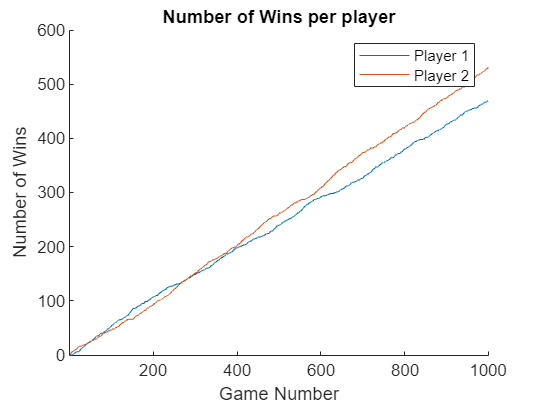

hold on;
plot(1:gameNumb-1, cumsum(data(:,1)), 'DisplayName', sprintf('Player %d', 1));

plot(1:gameNumb-1, cumsum(data(:,2)), 'DisplayName', sprintf('Player %d', 2)); % Plot the cumulative number of wins for each player

xlim([1 gameNumb])
hold off;
title('Number of Wins per player');
xlabel('Game Number');
ylabel('Number of Wins');
legend();

**Q: After **looking at the data, does it meet your expectations? Why/why not? Name at least two interesting features of your visualization, and explain why it is interesting and what you can learn from this.

***Answer: After looking at the data it did not meet my expectations other than we get two lines that kind of looks like staircases and that they arrive at somewhat the same result, however what is unexpected is that player 2 ends up getting the most wins, beating player 1 with 62 wins.***

***What suprised me is that the wins was relatively even from at the first 400 games and then afterwards player 2 starts taking a noticable lead  until the last game 1000. This is interesting because it suddenly happens after 400 games while before player 1 and 2 switch on who is in the lead. What can be learned from this is that the more simulations we have the easier it becomes to see the advantage that player 1 has. If we simulated only a couple of hundred games it would not be nearly as easy to spot any differences.***

### 2.3.2: Visualize the Data - Turn Frequencies

**Q: Before** looking at the data, take a moment to think about what you expect and why? How will the distribution of turn frequencies per game look (describe your expectation with words or include an image/sketch)? Will there be outliers? What do you think is the minimum number of turns for a game to be won? What about the maximum?

***Answer: I would maybe imagine a normal distriubtuion where we have most turns centering around a mean. There might be some outliers that might skew the distribution up or down, say for example if the max number of turns was 700 and the second max number of turns was 300 then the distribution would be pretty skewed from this one outlier. I think in theory that this is posible since it is hard to say what the maximum number of turns is.***

***I think the minimum number of turns for a game to be won if we look at the board is 5 (but the way we collect the data it will count as 4 if player 1 wins) turns where we hit two ladders, and no snakes. The maximum number of turns is hard to say, cause ther is a chance to play the game for ever if players always hit a snake before finishing, if i were to guess i would say the max number of turns would be about 500.***

Now plot the data as a [**bar chart**](https://se.mathworks.com/help/matlab/ref/bar.html) where:

- The **x-axis** shows the number of turns to finish a game

- The **y-axis **show the number of games that finished with a certain amout of turns (for example, if x=20, then the corresponding y-value would be the number of games that ended in 20 turns)

- The chart should have a proper title as well as axis titles

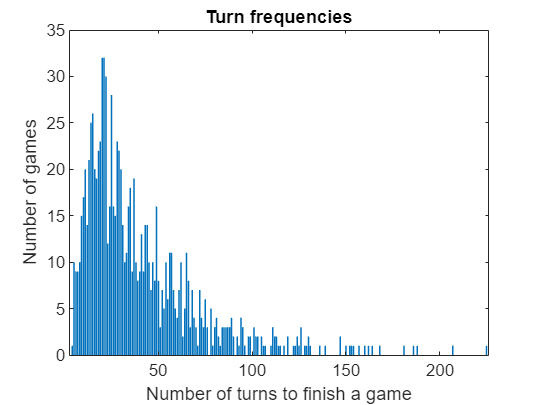

% TODO

[unique_values, ~, index] = unique(turnFreq);
counts = histcounts(index, numel(unique_values));

% Plot bar chart
b = bar(unique_values, counts);
b.EdgeColor ="none";
xlabel('Number of turns to finish a game');
ylabel('Number of games');


title('Turn frequencies');

**Q: After **looking at the data, does it meet your expectations? Why/why not? Name at least two interesting features of your visualization, and explain why they are interesting and what you can learn from this.

***Answer: The minimum was 4 turns so that was the same as my expectations, while the maximum was 225 (can see this all the way to the right of plot) this was lower than i expected. ***

***The distribution does not exactly resemble a normal distributuion however it does start low then high and then low again, but as i predicted the outliers that are on the far right side (the big values) skew the distribution, without those the distribution could look more like a normal distribution i think.***

***Some interesting points from the visualization that we can see is:***

- ***The max values are spaced far from each the seccond max value is 207 and the max value is 225. So it seems that the higher we go the more spaced out the values become and the less likely it is that we have those "number of turns to finish a game" more than once.***

- ***The most common number of turns it takes to finish a game is 20 and 21 turns, this happened 31 times each, this is not that much when we take into account that 1000 games was simulated.***

- ***We can see from the visualization that the most common number of turns it takes to finish snakes and ladders lies between 5 and 50 turns ( this is just purely analytical by looking at the graphs and might not be exactly right).***

### 2.3.3: Visualize the Data - Tile Frequencies

**Q: Before** looking at the data, take a moment to think about what you expect and why? Are some tiles more likely to be stepped on, why/why not? Will there be a general trend within the board (e.g., top to bottom or left to right)? Based on your knowledge from the previous task, what do you think could be a path taken to win in the smallest amout of turns? 

***Answer: Tiles 1,2,20,4,5,14 are more likely to be stepped on than the others because one of these always will be stepped on at the start of a turn, since both players start the same place, after this it is a bit harder to predict because now there will be many more different outcomes. Also tile 1 has two snakes going to it making it more likely that a player will land here.***

***All of the snake heads and all of the ladder starts wil not have any frequency because a player can never have their position on one of these tiles aswell. So if we look at row 5 with 4 snake heads and 1 ladder start we can safely assume that this row wil have low tile frequency***

***Because of this aswell i imagine that there will be more tile frequency at the bottom than at the top, one other reason for this is because there is more snakes than ladders and these snakes usualy takes the player further down than the ladders takes players up.***

***The path to win in smallest amount of turns would be tile (6 to 14, 17 to 74, 74 to 81, 81 to 98 and 98 to win), this path can take 5 turns or 4 turns if player 1 wins, this is unlikely because in the simulations it only happened 1 time for 4 turns and 10 for 5 turns.***

Now plot the data as** three **[**heatmaps**](https://se.mathworks.com/help/matlab/ref/heatmap.html) where:

- The tiles of the heatmaps show the frequency of the corresponding tiles of the board (imagine overlaying the board on the heatmap to verify that you have the correct layout)

- The first heatmap should show the average frequency for each tile during the 1000 simulated games

- The second heatmap should show the frequency for each tile during the game with the highest number of turns (if there is more than one with the same number of turns, chose one)

- The third heatmap should show the frequency for each tile during the game with the lowest number of turns (if there is more than one with the same number of turns, chose one)

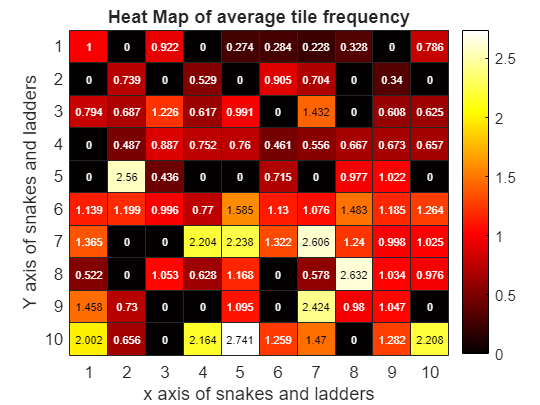

% TODO

% get the average values for each tile
avgTile = mean(tileFreq, 3);

% plot it in a heat map and add the colormap hot to it 
 
heatmap(avgTile, 'Colormap', hot);
xlabel('x axis of snakes and ladders'); %add x-axis label
ylabel('Y axis of snakes and ladders'); %add y-axis label
title('Heat Map of average tile frequency'); %add title

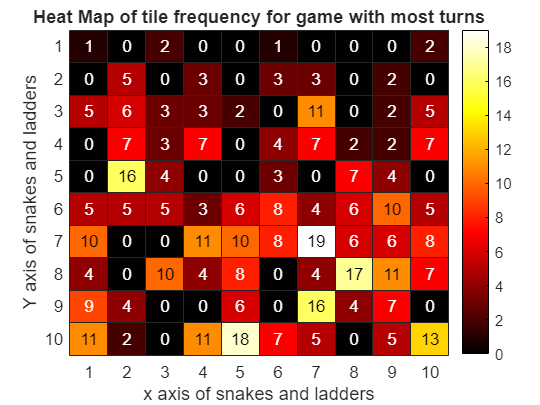

%% 2 
% find the max value in turnFreq and find its index. Use this index in
% tileFrequency matrix to find the tile with highest...
[Max, I] = max(turnFreq);
maxTile = tileFreq(:, :, I);
heatmap(maxTile, 'Colormap', hot);
xlabel('x axis of snakes and ladders'); %add x-axis label
ylabel('Y axis of snakes and ladders'); %add y-axis label
title('Heat Map of tile frequency for game with most turns'); %add title

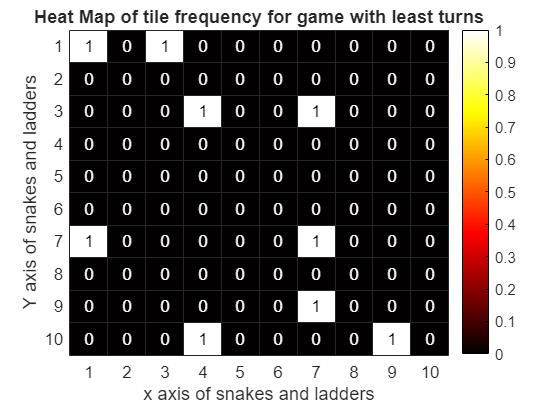


%%3
% find the min value in turnFreq and find its index. Use this index in
% tileFrequency matrix to find the tile with highest...
[Min, IM] = min(turnFreq);

minTile = tileFreq(:, :, IM);
heatmap(minTile, 'Colormap', hot);
xlabel('x axis of snakes and ladders'); %add x-axis label
ylabel('Y axis of snakes and ladders'); %add y-axis label
title('Heat Map of tile frequency for game with least turns'); %add title

**Q: After **looking at the data, does it meet your expectations? Why/why not? Name at least three interesting features of your visualizations, and explain why they are interesting and what you can learn from this.

***Answer: ***

***The heatmaps mostly met my expectations, there is most heat in the bottom and then the values go generaly lower towards the top. Also the snake head and ladder starts have 0 in tile frequency something that was also expected. Tile 5 was the most common tile to land on something that is not so suprising given that it is among the first 6 tiles a player can land on that i mentoned in my expectations.***

***What suprises me is that tile 59 was one of the other most common tile to land on, i am not sure why this is but this might be because it is in almost in the middle of the board, and it is in a snake tail position.***

***We can also se that in the heatmap of the game with least turns that the player that wins follows the expected route.***

***Some interesting things that we can see from our heatmap:***

- ***generaly the most common tiles to land on are snake tails or ladder endings. However it seem that snake tails are more common to land on than ladder endings if we look at the top 5 most common tiles to land on we see that 3 are snake tails and 2 are ladder endings.***

- ***From the heatmap we can also learn that it is much more common to be in the lower half of the board than the top of the board, as we have more heat in the bottom half.***

- ***In the heat map of the game with most amount of turns we can see that the heatmap resembles the heatmap of the average tiles. We can learn that games with higher turns will have tile frequency more like the average tile frequency compared to games with lower turns. The color from the average heatmap and the color for the heatmap of most turns are very similar.***

## Functions

**Task 1.1: **Function to simulate a dice throw. It should return a random integer between 1 and 6. 

function value = rolldice()
    %TODO 
    %fix the function so that it returns a random integer between 1 and 6
    % change it to built in function randi that
    % returns random integer between 1 and 6
    value = randi([1 6]);
end

**Task 1.2: **

function moveGamePiece(dice,activeposition,passiveposition,activecolor,passivecolor,board)

if dice==0
    
    %TODO------------------------------------
    %Compute the x and y position of the figures.
    %dice==0 means that a special event just happened, thus you move the
    %token to the final position without transition.
    %The position is given in pixel position of the board, the board has the
    %resolution of 600x600 pixel. Each field is 60x60 pixels big.
   
    %The active position variable tells the position of the player as value
    %between 0 and 100. This is the only variable you need in this section.
    %Note that the player is going to the right in the lowest row, to the
    %left in the second lowest and so on.
    


    % caclulate the row and column as a position between 0 and 9
    % if row number is odd we go left, if row number is even we go right
    row = 9 - floor((activeposition - 1) / 10);
    if mod(row, 2) == 0
        col = 9 - mod(activeposition - 1, 10);
    else
        col = mod(activeposition - 1, 10);
    end
    posX = col * 60 + 30;
    posY = row * 60 + 30;
    

    %------------------------------------

    figure(1)
    hold on
    imshow(board)

    axis([0 600 0 600])
    plotPlayer(activecolor, posX, posY)
    % Display the passive player
  
    %TODO------------------------------------
    %Exactly the same computation as above. This time you change
    %activeposition with passiveposition.


    %The same calculation as above
    row = 9 - floor((passiveposition - 1) / 10);
    if mod(row, 2) == 0
        col = 9 - mod(passiveposition - 1, 10);
    else
        col = mod(passiveposition - 1, 10);
    end
    posX = col * 60 + 30;
    posY = row * 60 + 30;


    %------------------------------------

    plotPlayer(passivecolor, posX, posY);

    
  
else % A normal dice throw
    

    startTile = activeposition - dice;
    endTile = activeposition;

    for m = startTile:endTile
    
        %TODO------------------------------------
        %Move the figure for the amount of the thrown die, pause on each
        %field shortly! Again use activeposition here!
        
        %
        row = 9 - floor((m - 1) / 10);
        if mod(row, 2) == 0
            col = 9 - mod(m - 1, 10);
        else
            col = mod(m - 1, 10);
        end
        posX = col * 60 + 30;
        posY = row * 60 + 30;

        %pause briefly between each step
        pause(0.5);

        %------------------------------------
           
        figure(1)
        hold on
        imshow(board)

        axis([0 600 0 600])
        plotPlayer(activecolor, posX, posY);


        %% Display the passive player
        
        %TODO------------------------------------
        %The passive figure does not move. Just reuse the code from the
        %first passive figure!
        % just the same as first passsive figure
        
        row = 9 - floor((passiveposition - 1) / 10);
        if mod(row, 2) == 0
            col = 9 - mod(passiveposition - 1, 10);
        else
            col = mod(passiveposition - 1, 10);
        end
        posX = col * 60 + 30;
        posY = row * 60 + 30;


        %------------------------------------

        plotPlayer(passivecolor,posX, posY)
        
    end
    
end

end


function plotPlayer(c, posX, posY)
    switch c
        case 1  %red
            plot(posX, posY, '.r', 'MarkerSize',60)

        case 2  %yellow
            plot(posX, posY, '.y', 'MarkerSize',60)

        case 3  %blue
            plot(posX, posY, '.b', 'MarkerSize',60)

        case 4  %green
            plot(posX, posY, '.g', 'MarkerSize',60)

        case 5  %cyan
            plot(posX, posY, '.c', 'MarkerSize',60)

        case 6  %magenta
            plot(posX, posY, '.m', 'MarkerSize',60)

        case 7  %white
            plot(posX, posY, '.w', 'MarkerSize',60)

    end
end


**Task 1.3: **Function to slide down snakes or climb up ladders. The matrix "snakes and ladders" contains for each board position, the new position the player should have after sliding/climbing. Given the input position, return the new board position.

function pos = checkPosChange(pos)
    snakesAndLadders = [100,63,98,87,96,95,94,93,25,91;
                        98,82,45,84,59,86,87,91,89,48;
                        80,79,78,77,76,28,74,86,72,71;
                        78,62,63,64,65,66,67,68,69,70;
                        23,59,58,76, 1,55,36,53,52,6;
                        41,42,43,44,45,46,47,48,49,50;
                        40, 5,59,37,36,35,34,33,32,31;
                        21,37,23,24,25,10,27,28,29,30;
                        20,19, 1,74,16,34,14,13,12,28;
                        1 , 2,20, 4, 5,14, 7, 4, 9,10];
    %TODO
    %return the new position of a player considering snakes and ladders

    %fixed error in row 5 column 10 this snake should take us down to 6 not
    %14 so changed value from 14 to 6
    %% changed row 2 column 1, changed row 5 column 4, row 7 column 3

    %We calculate the row based on the position between 1 and 10 now
    %instead of 0 and 9 so that we can index the matrix
    row = 10 - floor((pos - 1) / 10);
    % if row is even we find column by modulo position and 10
    %if row is odd we find culumn by subtracting modulo from 10 accounting
    %for the zig zag pattern
    if mod(row, 2) == 0
        col = 1 + mod(pos - 1, 10);
    else
        col = 10 - mod(pos - 1, 10);
    end

    % if position is the same as the index in matrix then we do not change
    % position, if it is not the same we change it to the new postition...
    if pos ~= snakesAndLadders(row,col)
        pos = snakesAndLadders(row,col);
    end

  
end


Funtion that initializes players by asking for the names of each player as input as well as their desired color. **You do not have to add anything to this function.**

function [playername1,playername2,playercolor1,playercolor2] = initializePlayers()
    % Initialization of the players
    fprintf('\n\t\t\t Welcome to The Game Of SNAKES & LADDERS')
    
    %% Player 1
    fprintf('\n Entering the name of player #1')
    playername1 = input('\nYour name is: ','s');
    fprintf('\n Welcome, %s!',playername1)
    
    % Make sure the player chooses a valid color
    colorOK = 0;
    while(colorOK==0)
        fprintf('\n Please specify the colour of your tile :')
        fprintf('\n 1: red; 2: yellow; 3: blue; 4: green; 5: cyan; 6: magenta; 7: white')
        playercolor1 = input('\n You select colour number: ');
        if (playercolor1 >=1 && playercolor1<=7)
            colorOK = 1;
        end
    end
    
    %% Player 2
    fprintf('\n Entering the name of player #2')
    playername2 = input('\nYour name is: ','s');
    fprintf('\n Welcome, %s!',playername2)
    
    % Make sure the player chooses the right color
    colorOK = 0;
    while(colorOK==0)
        fprintf('\n Please specify the colour of your tile :')
        fprintf('\n 1: red; 2: yellow; 3: blue; 4: green; 5: cyan; 6: magenta; 7: white')
        playercolor2 = input('\n You select colour number: ');
        if (playercolor1 == playercolor2)
            fprintf('\n Please select a different color than %s', playername1)
        else
            if (playercolor1 >=1 && playercolor1<=7)
                colorOK = 1;
            end
        end
    end
end

